cnc_params
 filelistFB = ["Angle_control_FB_29-Apr-2025_14-39-52.mat", "Angle_control_FB_29-Apr-2025_14-43-14.mat", "Angle_control_FB_29-Apr-2025_14-47-31.mat", "Angle_control_FB_29-Apr-2025_14-49-13.mat", "Angle_control_FB_29-Apr-2025_14-52-22.mat", "Angle_control_FB_29-Apr-2025_14-56-16.mat", "Angle_control_FB_29-Apr-2025_14-59-10.mat", "Angle_control_FB_29-Apr-2025_15-04-08.mat", "Angle_control_FB_29-Apr-2025_15-06-02.mat", "Angle_control_FB_29-Apr-2025_15-09-49.mat", "Angle_control_FB_29-Apr-2025_15-11-09.mat", "Angle_control_FB_29-Apr-2025_15-21-00.mat", "Angle_control_FB_29-Apr-2025_15-25-22.mat", "Angle_control_FB_29-Apr-2025_15-26-51.mat", "Angle_control_FB_29-Apr-2025_15-28-52.mat"];


ClosedLoopM0 = "lab6/data/FB/"+filelistFB([1 4]);
ClosedLoopM1 =  "lab6/data/FB/"+filelistFB([2 5]);

P0 = P_ext(1);
P1 = P_ext(2);

b21 = (k *r /Ra)/J_tilda;


A0 = [0 1 ; 
    0 -P0];
A1 = [0 1 ; 
    0 -P1];
B = [0 ; -b21];
C = [1 0];


% M = [0; 1/(J_tilda *eta_g *eta_m)]; % For torque disturbance
M = B; % For Volt disturbance


G0ss = ss(A0,B,C,0);
G1ss = ss(A1,B,C,0);


P0 = P_ext(1);
mu0 = mu_ext(1);
P1 = P_ext(2);
mu1 = mu_ext(2);
G0 = tf(-mu0,[1/P0 1 0]);
G1 = tf(-mu1,[1/P1 1 0]);


% PD0 = pid(-20.82,0,-0.4158 );
PD0 = C0;
T0 = feedback(G0*PD0,1,-1);
% T0=c2d(T0,1/500);

% exp_data = load(ClosedLoopM0(1)).data;
% 
% t = exp_data(1,:)';
% y = exp_data(2,:)';
% y_ref = exp_data(10,:)';
% 
% u = y_ref;
% 
% idd = iddata(y,u,1/500);
% Data = idd;
% sys = T0;
% 
% resid(Data,sys)

% compare(sys,Data);

% 
% yp = predict(sys,Data,1);

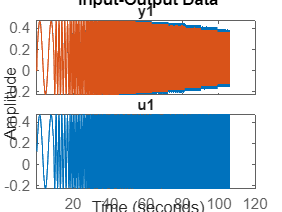

% 
% plot(idd,yp)

% 

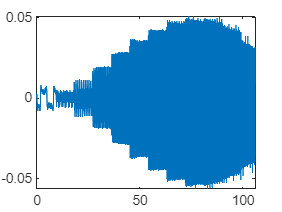

% 
% er = y - yp.OutputData;
% 
% [xc,lags] =xcorr(er,500,'normalized');
% 
% plot(t,er)

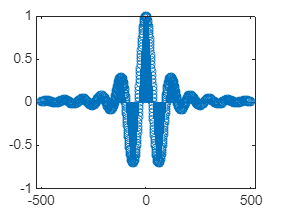

% 
% stem(lags,xc)